env = MyEnvironment;
validateEnvironment(env)
obsInfo = getObservationInfo(env)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "state"
    Description: [0×0 string]
      Dimension: [2 1]
       DataType: "double"


actInfo = getActionInfo(env)

actInfo =   rlFiniteSetSpec with properties:

       Elements: [41×1 double]
           Name: "action"
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


initOpts = rlAgentInitializationOptions(NumHiddenUnit=128);
rng(0)
agent = rlPGAgent(obsInfo,actInfo,initOpts);
actorNet = getModel(getActor(agent));
criticNet = getModel(getCritic(agent));
criticNet.Layers

ans =   6×1 Layer array with layers:

     1   'input_1'       Feature Input     2 features
     2   'fc_1'          Fully Connected   128 fully connected layer
     3   'relu_body'     ReLU              ReLU
     4   'fc_body'       Fully Connected   128 fully connected layer
     5   'body_output'   ReLU              ReLU
     6   'output'        Fully Connected   1 fully connected layer

summary(criticNet)

   Initialized: true

   Number of learnables: 17k

   Inputs:
      1   'input_1'   2 features



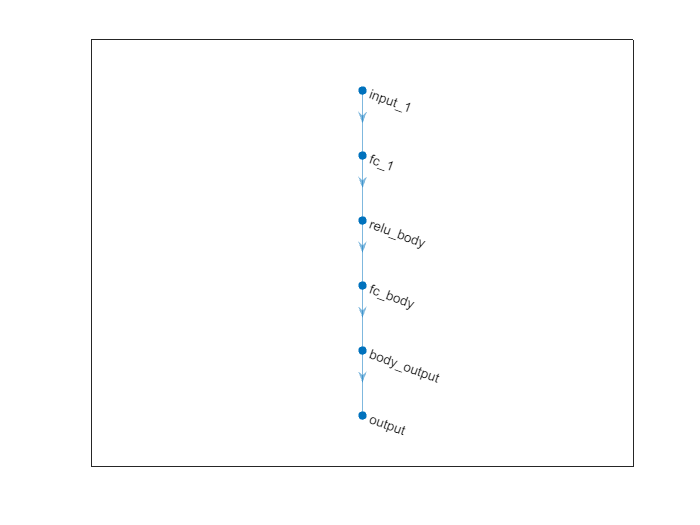

plot(criticNet)

plot(actorNet)

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[-12]}


criticOpts = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);
actorOpts = rlOptimizerOptions(LearnRate=1e-03,GradientThreshold=1);

trainOpts = rlTrainingOptions(...
    MaxEpisodes=500,...
    MaxStepsPerEpisode=1000,...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=-500);

doTraining = true;
if doTraining
    % Use the rlEvaluator object to measure policy performance every 10
    % episodes
    % evaluator = rlEvaluator(...
    %     NumEpisodes=1,...
    %     EvaluationFrequency=10);
    % Train the agent.
    trainResults = train(agent,env,trainOpts);
else
    % Load the pretrained agent for the example.
    load("savedAgents\Agent10.mat","saved_agent")
end

simOpts = rlSimulationOptions(MaxSteps=500);
plot(env)
experience = sim(env,agent,simOpts)

experience = struct with fields:
       Observation: [1×1 struct]
            Action: [1×1 struct]
            Reward: [1×1 timeseries]
            IsDone: [1×1 timeseries]
    SimulationInfo: [1×1 struct]
